# ELEC5305 Acoustics, Speech and Signal Processing (Lab Report 1)

Author: Xiaoyu Hu

SID: 530598444

Date: 05 / 09 / 2025

## 1. Objective

    The goal of this report is to design a custom MATLAB Live Script that integrates fundamental concepts of digital signal processing through practical examples. Using audio input as the main medium, the project covers time-domain analysis, pre-emphasis and de-emphasis filtering, short-time Fourier transform, additive and FM sound synthesis, and short-time feature extraction such as zero-crossing rate, energy, spectral centroid, and rolloff. Together, these modules showcase how theoretical techniques can be applied to real audio data. The objective is to gain hands-on experience with analysis, synthesis, and feature extraction for speech and music signals.

## 2. Background

    This report applies a variety of audio signal processing concepts to demonstrate analysis, transformation, and synthesis of audio signals. Core ideas include time-domain and frequency-domain representations, which allow observation of waveform behavior and spectral distribution [1]. Pre-emphasis and de-emphasis filtering are introduced to highlight and restore high-frequency content, techniques commonly used in speech processing [1], [2]. Short-Time Fourier Transform (STFT) provides a time–frequency representation, useful for analyzing nonstationary signals [1], [3]. Additive and FM synthesis illustrate how complex tones. Feature extraction methods such as zero-crossing rate, energy, spectral centroid, and rolloff are used to characterize audio signals. These methods integrate both fundamental theory and practical tools covered in lab materials and lectures, reinforcing how digital signal processing principles can be applied to real-world tasks of audio analysis and manipulation.

## 3. Implementation

    This report implements a sequence of audio signal processing tasks using MATLAB to analyze, synthesize, and classify audio signals. 

    In Part 1, an input audio file is loaded using audioread(), resampled with resample() to 22.05 kHz, and played back with audioplayer(). An exponential sine sweep is generated and recorded using audiorecorder() to estimate the impulse response by convolution with an inverse filter.

    In Part 2, time–frequency analysis is performed with spectrogram(), showing how spectral content evolves over time. Pre-emphasis and de-emphasis filters are applied using filter(), based on the FIR equation：


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -\alpha x\left\lbrack n-1\right\rbrack$$


The relationship between the Discrete-Time Fourier Transform (DTFT) and the Fast Fourier Transform (FFT) is demonstrated, reinforcing spectral decomposition concepts.

    In Part 3, I implements the Short-Time Fourier Transform (STFT). The signal is framed and windowed with a Hann window, then transformed by FFT:


$$X\left(k,m\right)=\sum_{n=0}^{L-1} x\left\lbrack n+\mathrm{mH}\right\rbrack \;w\left\lbrack n\right\rbrack \;e^{-\mathrm{j2}\pi \mathrm{kn}/N}$$


where L is window size and H is hop size. The inverse STFT uses overlap-add reconstruction to verify recovery of the original waveform.

    In Part 4, I explore sound synthesis through additive synthesis and frequency modulation. The additive model combines exponentially decaying sinusoids to create a bell-like tone:


$$x\left(t\right)=\sum_i A_i \;e^{\frac{-t}{\tau_i }} \cos \left(2\pi f_i t\right)$$


The FM model produces rich spectra by modulating a carrier frequency with a sinusoidal modulator.

    In Part 5, I extract short-time features including zero-crossing rate, short-time energy, spectral centroid, and rolloff. These features are plotted against time. The following comprehensive pipeline demonstrates practical applications of core audio signal processing concepts:

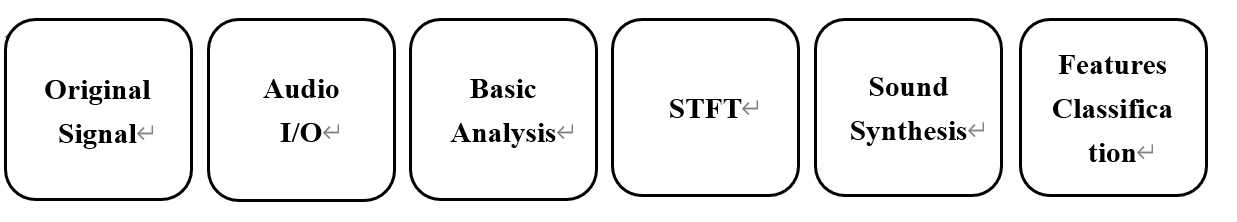

## 4. Code & Results

### 4.1 Audio I/O

    In this part, I first obtained the audio signal by a recording. After that, I resampled the signal to 22.05 kHz and plotted its waveform. To explore selective playback, I extracted and listened to a short segment between one and three seconds. For time–frequency monitoring, I used the DSP System Toolbox to stream the signal into a spectrum analyzer, which showed how frequency content evolved over time. Finally, I generated an exponential sine sweep (ESS), played it while recording, and then convolved the recorded signal with its inverse filter to estimate the impulse response. The resulting plot showed a sharp direct peak followed by reflections.

clear; clc; close all;

% ==== Global parameters ====
fsTarget   = 22050;  % Target sampling rate (analysis will use this rate)
durDefault = 5;      % Fallback duration (s) if an input file is not provided
rng(1);              % Fixed random seed for reproducibility

% -------------------------------
% Part 1: Audio I/O
% -------------------------------

% Feature switches (enable/disable individual demonstrations)
doStreaming  = true;   % Streaming spectrum (requires DSP System Toolbox)
doRegionPlay = true;   % Play a short region from the audio
doESS        = true;   % Exponential sine sweep (ESS): sweep + record + deconvolve

% Defensive reassign (normally not triggered; keeps script robust)
if ~exist('fsTarget','var'),   fsTarget   = 22050; end
if ~exist('durDefault','var'), durDefault = 5;     end

% ---- Read an audio file, or synthesize a fallback if reading fails ----
try
    % Interactive file picker; common formats supported by audioread
    [fn, fp] = uigetfile({'*.wav;*.mp3;*.flac;*.m4a','Audio Files'}, 'Pick an audio');
    if isequal(fn,0), error('No file'); end
    [xIn, fsIn] = audioread(fullfile(fp, fn));
    fprintf('[load] %s (fs=%d, ch=%d, N=%d)\n', fn, fsIn, size(xIn,2), size(xIn,1));
catch
    % Fallback: synthesize a decaying multisine (musical A triad-ish) at fsIn
    fsIn = 48000;
    t0   = (0:fsIn*durDefault-1)'/fsIn;
    xIn  = (0.6*sin(2*pi*220*t0) + 0.4*sin(2*pi*330*t0) + 0.3*sin(2*pi*440*t0)).*exp(-t0/3);
    fprintf('[synth] fallback (fs=%d)\n', fsIn);
end

[load] Report1_Input.wav (fs=44100, ch=1, N=308700)


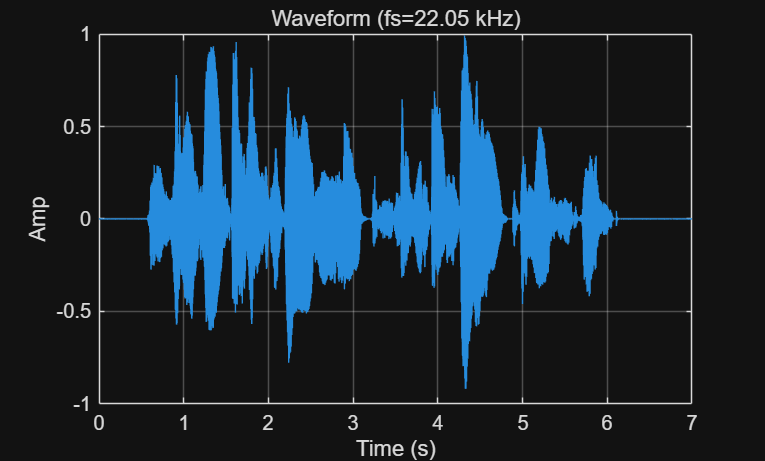


% ---- Play the original audio (convert to mono + normalize) ----
y0 = xIn;
if size(y0,2)>1, y0 = mean(y0,2); end     % Convert multi-channel audio to mono
y0 = y0 / max(abs(y0)+eps);               % Normalize to avoid clipping
p0 = audioplayer(y0, fsIn);
playblocking(p0);                         % Blocking playback for demonstration
pause(0.05); drawnow;

% ---- Resample to target fs for consistent analysis parameters ----
x  = y0;                                   % Keep a working copy for processing
fs = fsTarget;
x  = resample(x, fs, fsIn);                % Resample to fsTarget
dur = numel(x)/fs;

% ---- Plot time-domain waveform ----
figure('Name','Waveform');
plot((0:numel(x)-1)/fs, x); grid on; xlabel('Time (s)'); ylabel('Amp');
title(sprintf('Waveform (fs=%g kHz)', fs/1000));

[stream] close spectrum window to stop


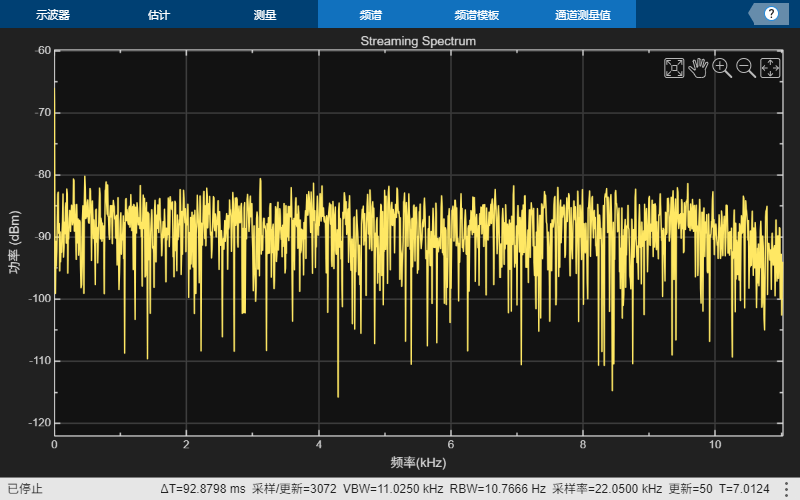


% ---- Region playback: play [1 s, 3 s] segment ----
if doRegionPlay
    seg = [1 3];                            % Segment in seconds
    i1  = max(1, round(seg(1)*fs));
    i2  = min(numel(x), round(seg(2)*fs));
    p1  = audioplayer(x(i1:i2), fs);
    playblocking(p1);
    pause(0.05); drawnow;
end

% ---- Streaming spectrum (optional; requires DSP System Toolbox) ----
if doStreaming
    try
        % Check toolbox classes and audiowrite availability
        hasDSP = (exist('dsp.AudioFileReader','class')==8) && (exist('dsp.SpectrumAnalyzer','class')==8);
        if hasDSP && exist('audiowrite','file')
            % Write temp .wav, then read in frames and feed SpectrumAnalyzer
            tmp = [tempname,'.wav']; audiowrite(tmp, x, fs);
            r = dsp.AudioFileReader(tmp, 'SamplesPerFrame', 1024, 'PlayCount', 1);
            sa = dsp.SpectrumAnalyzer('SampleRate', fs, 'PlotAsTwoSidedSpectrum', false, 'Title','Streaming Spectrum');
            fprintf('[stream] close spectrum window to stop\n');
            while ~isDone(r), sa(r()); end
            release(sa); release(r); delete(tmp);
        else
            fprintf('[stream] DSP toolbox missing -> skip\n');
        end
    catch ME
        fprintf('[stream][warn] %s\n', ME.message);  % Handle headless or device errors gracefully
    end
end

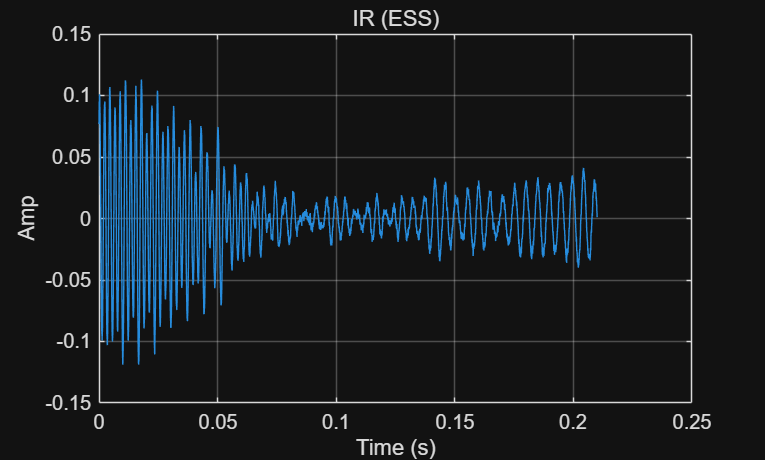


% ---- ESS: play sweep, record response, deconvolve to estimate IR ----
% Idea: the recorded sweep convolved with inverse-sweep approximates the room/system IR.
if doESS
    T = 3; f1 = 50; f2 = min(fs/2-200, 18000);          % Sweep duration and band (leave headroom to Nyquist)
    [sweep, invSweep] = ess_generate(fs, T, f1, f2);    % Generate ESS and its inverse filter

    recObj = audiorecorder(fs, 16, 1);                  % fs, 16-bit, mono
    pS = audioplayer(sweep*0.2, fs);                    % Lower amplitude (0.2) to avoid clipping
    record(recObj);                                     % Start recording before playback
    playblocking(pS);
    stop(recObj);

    yRec  = getaudiodata(recObj);                       % Recorded output
    Hfull = conv(yRec, invSweep, 'full');               % Deconvolution via convolution with inverse sweep
    [~, i0] = max(abs(Hfull));                          % Peak indicates IR alignment
    IR = Hfull( max(1,i0-round(fs*0.01)) : min(length(Hfull), i0+round(fs*0.2)) ); % Take a window around the peak

    figure('Name','Estimated IR');
    plot((0:numel(IR)-1)/fs, IR); grid on; xlabel('Time (s)'); ylabel('Amp'); title('IR (ESS)');
end

### 4.2 Basic Analysis

    In this part, I analyzed the resampled audio in both time and frequency domains. I first used the spectrogram with a Hann window to show how spectral content changes over time. Then I applied a pre-emphasis filter to highlight high frequencies and a de-emphasis filter to restore the original shape. In short time plots, the pre-emphasized signal showed sharper edges, and the spectrum confirmed the boost in high-frequency energy. Finally, I compared the Discrete-Time Fourier Transform (DTFT) with the Fast Fourier Transform (FFT). The dense DTFT gave a smooth curve, while the FFT showed sampled bins that matched the same spectral pattern.

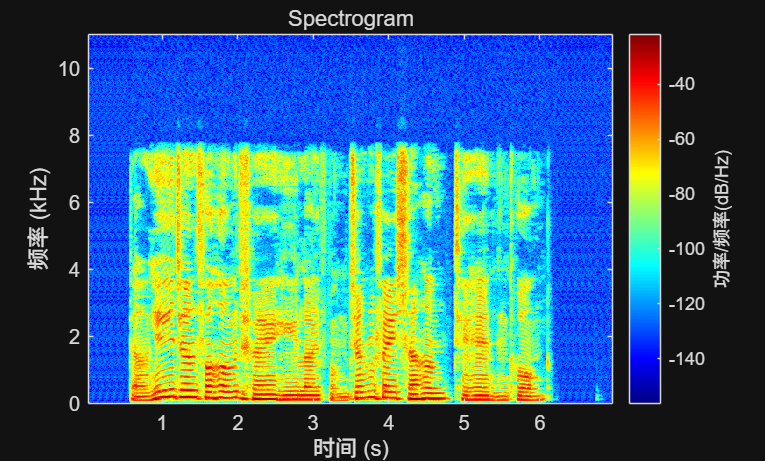

% --------------------------------
% Part 2: BASIC SIGNAL ANALYSIS
% --------------------------------

% ---- Spectrogram (STFT magnitude over time) ----
win = hann(1024); ovlp = 768; nfft = 2048;             % 1024-pt Hann, 75% overlap, 2048-pt FFT
figure('Name','Spectrogram');
spectrogram(x, win, ovlp, nfft, fs, 'yaxis'); title('Spectrogram'); colormap jet;

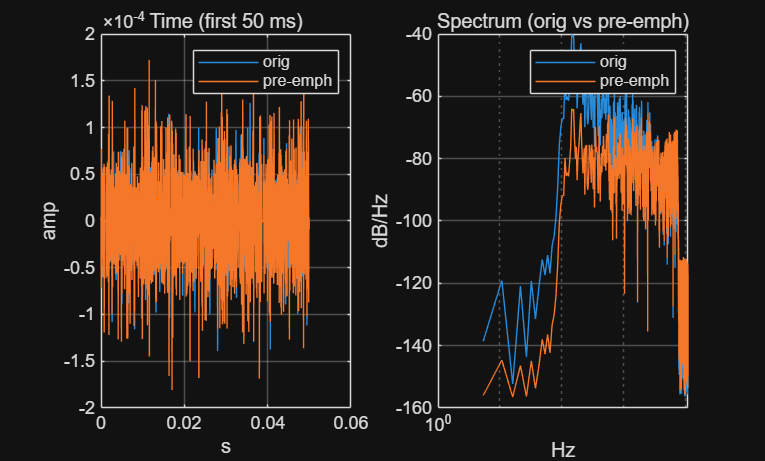


% ---- Pre-emphasis and de-emphasis (common in speech) ----
a = 0.95; b = [1 -a];                                  % H(z)=1-az^{-1}: high-frequency boost
x_pe = filter(b, 1, x);                                % Pre-emphasis
x_rec = filter(1, b, x_pe);                            % De-emphasis (inverse), for invertibility check

% ---- Visualize first 50 ms in time & compare spectra before/after ----
Nshow = min(length(x), round(0.05*fs));
t = (0:Nshow-1)/fs;

figure('Name','PreEmphasis: time & spectrum');
subplot(1,2,1);
plot(t, x(1:Nshow)); hold on; plot(t, x_pe(1:Nshow));
grid on; title('Time (first 50 ms)'); legend('orig','pre-emph'); xlabel('s'); ylabel('amp');

subplot(1,2,2);
nfft = 4096;
[Px, f]  = periodogram(x,    [], nfft, fs, 'power');   % Power spectral density
[Ppe, ~] = periodogram(x_pe, [], nfft, fs, 'power');
semilogx(f, 10*log10(Px+eps)); hold on;                % Log frequency axis highlights HF changes
semilogx(f, 10*log10(Ppe+eps));
grid on; xlabel('Hz'); ylabel('dB/Hz'); title('Spectrum (orig vs pre-emph)'); legend('orig','pre-emph');


% ---- Numeric check: de-emphasis reconstruction error (lower is better) ----
recErr = 20*log10( rms(x - x_rec) / (rms(x)+eps) );
fprintf('[de-emph] reconstruction error: %.2f dB (lower is better)\n', recErr);

[de-emph] reconstruction error: -328.76 dB (lower is better)


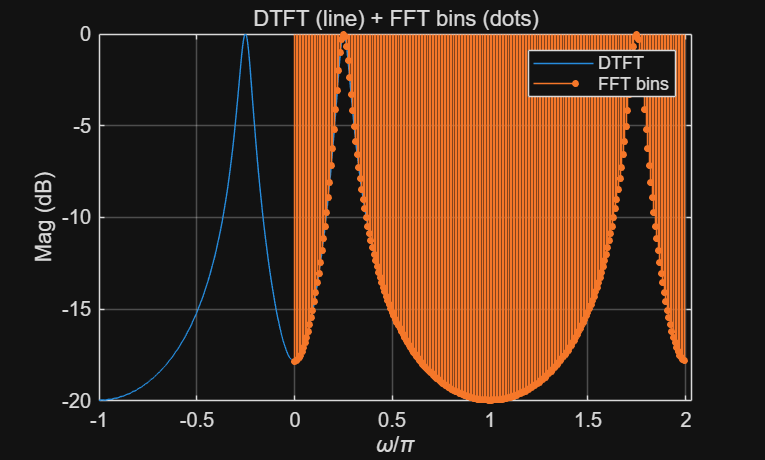


% ---- DTFT vs FFT demonstration ----
% DTFT: spectrum on a dense, continuous-like frequency grid.
% FFT: spectrum sampled on discrete frequency bins.
n = 0:63;
x_test = (0.9.^n).*cos(2*pi*0.125*n);                  % Exponentially decaying cosine
w = linspace(-pi, pi, 2048);
Xdtft = dtft(x_test, n, w);                            % Dense frequency sampling (DTFT)

Nfft = 256; k = 0:Nfft-1; Xfft = fft(x_test, Nfft); omega = 2*pi*k/Nfft;
Ad = abs(Xdtft); Ad = Ad./(max(Ad)+eps);               % Normalize both to 0 dB peak
Af = abs(Xfft);  Af = Af./(max(Af)+eps);

figure('Name','DTFT vs FFT (one plot)');
plot(w/pi, 20*log10(Ad+eps)); hold on;                 % DTFT as continuous curve
stem(omega/pi, 20*log10(Af+eps), 'filled', 'MarkerSize', 3); % FFT bins as discrete dots
grid on; xlabel('\omega/\pi'); ylabel('Mag (dB)'); title('DTFT (line) + FFT bins (dots)');
legend('DTFT','FFT bins');

### 4.3 STFT

    In this part, I used STFT to look at how the frequencies in my audio change over time. I cut the signal into short frames with a Hann window and ran FFT on each frame to get a spectrogram. Then I used inverse STFT with overlap-add to rebuild the signal, and the result was almost the same as the original, so the method worked correctly.

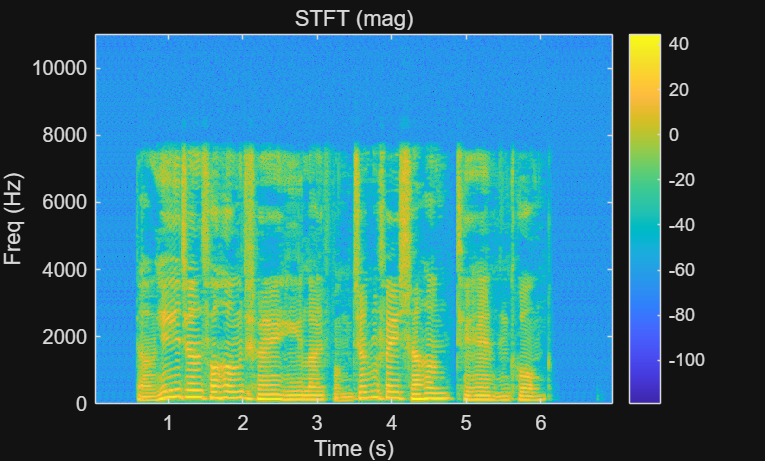

% -----------------------------
% Part 3: STFT + iSTFT
% -----------------------------
Lwin  = 1024;              % Window length (samples)
Hop   = 256;               % Hop size (samples) -> 75% overlap with Hann
NfftS = 2048;              % FFT size for STFT (>= Lwin is common)

[Sstft, Fstft, Tstft] = stft_simple(x, fs, Lwin, Hop, NfftS); % Custom STFT (explicit framing)

% Visualize magnitude (dB) of the lower half (0..Nyquist)
Kst = floor(NfftS/2);
figure('Name','STFT magnitude (dB)');
imagesc(Tstft, Fstft(1:Kst), 20*log10(abs(Sstft(1:Kst,:))+eps));
axis xy; xlabel('Time (s)'); ylabel('Freq (Hz)'); title('STFT (mag)'); colorbar;


% Invert via iSTFT and evaluate reconstruction error
x_rec_stft = istft_simple(Sstft, Lwin, Hop);
Nmin = min(length(x), length(x_rec_stft));
err_db = 20*log10( rms(x(1:Nmin) - x_rec_stft(1:Nmin)) / (rms(x(1:Nmin))+eps) );
fprintf('[STFT] recon error: %.2f dB (lower is better)\n', err_db);

[STFT] recon error: -66.19 dB (lower is better)


### 4.4 Sound Synthesis

    In this part, I made new sounds using additive synthesis and FM synthesis. For the additive part, I added several sinusoids with different frequencies and exponential decays to create a bell-like tone. For the FM part, I used a carrier frequency with a low-frequency modulator to produce a richer spectrum. The plots showed the waveforms and their spectra.

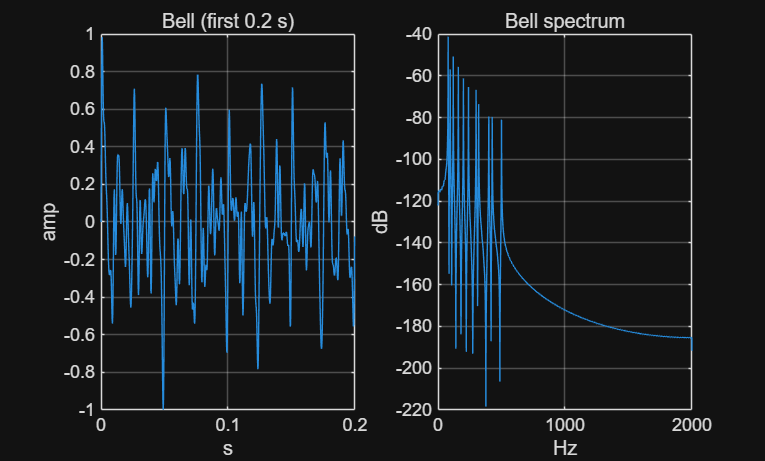

% -----------------------------
% Part 4: SOUND SYNTHESIS
% -----------------------------
fs_syn = 4000;   % Lower fs for quick synthesis demos

% ---- Additive "bell" (harmonics/partials with different decays) ----
dur = 3; t = (0:fs_syn*dur-1)'/fs_syn;
freqs = [80 96 120 160 200 240 300 320 400 427 500];     % Example partials
amps  = [1.0 0.8 0.7 0.6 0.5 0.45 0.4 0.35 0.3 0.25 0.2]; % Relative amplitudes
taus  = [1.00 0.90 0.85 0.80 0.75 0.70 0.65 0.60 0.55 0.50 0.45]; % Decay time constants

S = sin(2*pi*t*freqs);               % Each column: one sinusoid at a given partial
E = exp(-t*(1./taus));               % Per-partial exponential decay
bell = sum(E .* (S .* amps), 2);     % Sum across partials to get the bell sound
bell = bell / max(abs(bell)+eps);    % Normalize for playback

% Plot first 0.2 s (time) and spectrum
figure('Name','Bell: wave + spec');
subplot(1,2,1);
plot(t(1:0.2*fs_syn), bell(1:0.2*fs_syn)); grid on; title('Bell (first 0.2 s)');
xlabel('s'); ylabel('amp');

subplot(1,2,2);
nfft = 4096;
[Pb,f] = periodogram(bell, [], nfft, fs_syn);
plot(f, 20*log10(Pb+eps)); grid on; xlabel('Hz'); ylabel('dB'); title('Bell spectrum');

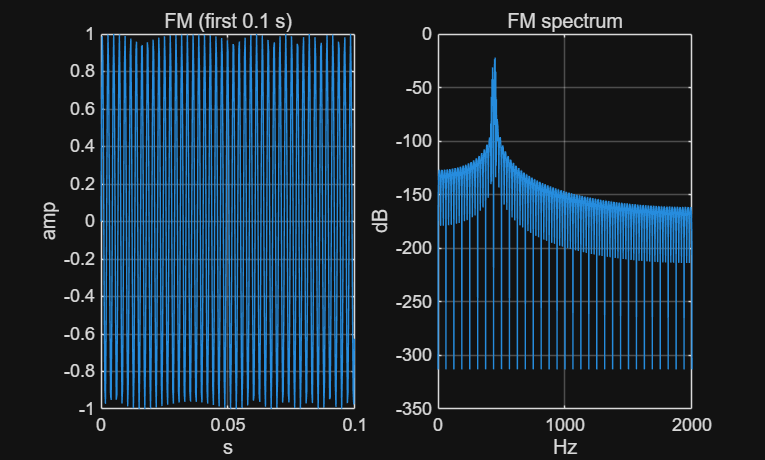

soundsc(bell, fs_syn);                 % Auto-scaled playback

% ---- Simple FM (carrier fc, modulator fm, modulation index beta) ----
dur_fm = 2; t2 = (0:fs_syn*dur_fm-1)'/fs_syn;
fc=440; fm=5; beta=2;                 % A4 carrier, slow vibrato-like modulation
fmSig = sin(2*pi*fc*t2 + beta*sin(2*pi*fm*t2));
fmSig = fmSig / max(abs(fmSig)+eps);

figure('Name','FM: wave + spec');
subplot(1,2,1);
plot(t2(1:0.1*fs_syn), fmSig(1:0.1*fs_syn)); grid on; title('FM (first 0.1 s)');
xlabel('s'); ylabel('amp');

subplot(1,2,2);
[Pf,ff] = periodogram(fmSig, [], nfft, fs_syn);
plot(ff, 20*log10(Pf+eps)); grid on; xlabel('Hz'); ylabel('dB'); title('FM spectrum');

soundsc(fmSig, fs_syn);

### 4.5 Features Classification

    In this part, I calculated some short-time features from the audio. I framed the signal and measured zero-crossing rate, short-time energy, spectral centroid, and spectral rolloff. The plots showed how these features changed over time. 

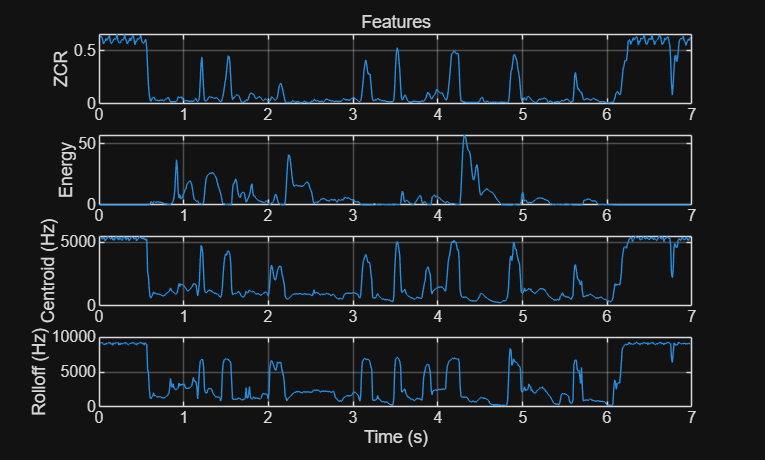

% --------------------------------
% Part 5: AUDIO FEATURES
% --------------------------------

% ---- Framing (25 ms window, 10 ms hop, Hann window) ----
winSec = 0.025; hopSec = 0.010;
[frm, tF] = frame_signal(x, fs, winSec, hopSec, @hann);

% ---- Basic short-time features: ZCR and Energy ----
Z = zcr(frm);                     % Zero-Crossing Rate per frame
E = sum(frm.^2, 1);               % Short-time energy per frame

% ---- Frequency-domain prep: per-frame FFT ----
L = size(frm,1);
Nfft = 2^nextpow2(L);
K = floor(Nfft/2);                % Use lower half (0..Nyquist)
F = (0:K-1) * (fs/Nfft);          % Frequency axis (Hz)
S = abs(fft(frm, Nfft, 1));       % Magnitude spectra per frame
S = S(1:K, :);

% ---- Spectral Centroid and Rolloff ----
Cent = (F * S) ./ (sum(S,1) + eps); % Centroid: energy "center of mass" in frequency
cumS = cumsum(S, 1);                % Cumulative energy per frame
thr  = 0.85 * cumS(end, :);         % Rolloff threshold at 85% cumulative energy
idx  = arrayfun(@(c) find(cumS(:,c) >= thr(c), 1, 'first'), 1:size(S,2));
Roll = F(idx);

% ---- Plot time series of features ----
figure('Name','Short-Time Features');
subplot(4,1,1); plot(tF, Z);    grid on; ylabel('ZCR');      title('Features');
subplot(4,1,2); plot(tF, E);    grid on; ylabel('Energy');
subplot(4,1,3); plot(tF, Cent); grid on; ylabel('Centroid (Hz)');
subplot(4,1,4); plot(tF, Roll); grid on; ylabel('Rolloff (Hz)'); xlabel('Time (s)');

function [frames, tFrames] = frame_signal(x, fs, winSec, stepSec, winfun)
    % Slice a 1-D signal into overlapping frames and apply a window.
    % Outputs:
    % - frames: L x N matrix (L: samples per frame, N: number of frames)
    % - tFrames: 1 x N vector of frame center times (s)
    if nargin < 5 || isempty(winfun), winfun = @hann; end
    x = x(:);
    L = round(winSec*fs);
    H = round(stepSec*fs);
    N = 1 + max(0, floor((numel(x)-L)/H));   % Number of frames (no zero padding)
    frames = zeros(L, max(1,N));
    w = winfun(L);                           % Default Hann window
    for i = 1:N
        idx = (1:L) + (i-1)*H;
        frames(:,i) = x(idx).*w;            % Windowed frame (reduces spectral leakage)
    end
    tFrames = ((0:N-1)*H + L/2)/fs;         % Frame-center times (s)
end

function z = zcr(frames)
    % Zero-crossing rate per frame.
    % Counts sign changes, normalized by frame length.
    sgn = sign(frames);
    sgn(sgn==0) = 1;                         % Treat zeros as positive for stable counting
    z = sum(abs(diff(sgn,1,1)),1) / (2*size(frames,1));
end

function X = dtft(x, n, w)
    % Numerical DTFT on a dense frequency grid w.
    % X(w) = sum_n x[n]*exp(-j*w*n)
    x = x(:).';      % 1 x N
    n = n(:);        % N x 1
    w = w(:).';      % 1 x M
    X = x * exp(-1j * (n * w));
end

function PlayTrackLine(x, fs, figPos, lineStyle)
    % Visualization helper: plot a signal and let the user click two points
    % to mark a time segment (no playback here; prints the selection only).
    if nargin<3 || isempty(figPos),   figPos   = []; end
    if nargin<4 || isempty(lineStyle), lineStyle = 'r:'; end
    x = x(:);
    t = (0:numel(x)-1)/fs;
    f = figure('Name','PlayTrackLine'); if ~isempty(figPos), set(f, 'Position', figPos); end
    plot(t, x); grid on; xlabel('Time (s)'); ylabel('Amplitude'); title('Click two points: start & end, then press ENTER');
    hold on;
    [xp, ~] = ginput; 
    if numel(xp) < 2, disp('Not enough points selected.'); return; end
    xs = max(0, min(xp(1), xp(2))); xe = min(t(end), max(xp(1), xp(2)));
    line([xs xs], ylim, lineStyle, 'LineWidth', 1.2);
    line([xe xe], ylim, lineStyle, 'LineWidth', 1.2);
    seg = x(round(xs*fs):max(round(xs*fs)+1, round(xe*fs)));
    fprintf('[PlayTrackLine] Playing %.3f–%.3f s (%.0f samples)\n', xs, xe, numel(seg));
end

function [u, invf] = ess_generate(fs, T, f1, f2)
    % Generate an exponential sine sweep u(t) and a simple inverse filter.
    % The inverse is built by time-reversing and amplitude shaping u(t).
    t = (0:1/fs:T-1/fs).';
    K = T/log(f2/f1);
    L = (2*pi*f1)*K;
    phase = L*(exp(t./K)-1);     % Exponential time mapping -> frequency grows exponentially
    u = sin(phase);              % Sweep signal
    g = flipud(u) ./ max(u.^2 + eps); % Approximate inverse (reverse + amplitude correction)
    invf = g;
end

function out = ternary(cond, a, b)
    % Minimal ternary helper (MATLAB does not have ?: operator)
    if cond, out = a; else, out = b; end
end

function [S, F, T] = stft_simple(x, fs, Lwin, Hop, Nfft)
    % Educational STFT: explicit framing -> windowing -> per-frame FFT.
    % Returns:
    % - S: Nfft x M complex spectrogram
    % - F: Nfft x 1 frequency axis (Hz)
    % - T: 1 x M frame-center times (s)
    x = x(:);
    winSec = Lwin / fs;
    hopSec = Hop  / fs;
    [frm, T] = frame_signal(x, fs, winSec, hopSec, @hann);
    if nargin < 5 || isempty(Nfft), Nfft = 2^nextpow2(Lwin); end
    S = fft(frm, Nfft, 1);                                % FFT along columns
    F = (0:Nfft-1).' * (fs/Nfft);                         % Frequency axis
end

function y = istft_simple(S, Lwin, Hop)
    % Educational iSTFT: IFFT per frame -> take first Lwin -> window -> OLA -> window^2 normalization.
    [Nfft, M] = size(S);
    w  = hann(Lwin, 'periodic');
    frm = real(ifft(S, Nfft, 1));
    frm = frm(1:Lwin, :) .* w;                            % Use first Lwin samples and reapply window
    ylen = (M-1)*Hop + Lwin;
    y    = zeros(ylen,1);
    wsum = zeros(ylen,1);
    for m = 1:M
        idx = (1:Lwin) + (m-1)*Hop;
        y(idx)    = y(idx)    + frm(:,m);                 % Overlap-add
        wsum(idx) = wsum(idx) + w.^2;                     % Accumulate window^2 for amplitude correction
    end
    nz = wsum > eps;
    y(nz) = y(nz) ./ wsum(nz);                            % Normalize where window coverage is nonzero
end

## 5. Discussion

    The spectrogram and STFT showed how the signal’s energy changed over time and frequency. Steady tones looked like horizontal lines, while noisy or sudden parts showed as vertical streaks. Pre-emphasis boosted the high frequencies, and de-emphasis almost perfectly restored the signal, which matched the theory. The additive “bell”produced several partials that faded over time, and FM synthesis created sidebands that changed with the modulation index. The short-time features were clear: energy matched the loudness, ZCR was higher in noisy parts, and centroid and rolloff increased when there were more high frequencies

    I also ran into some practical issues. At first, using sound or soundsc caused the audio to get cut off when the code moved on, so I switched to audioplayer with playblocking, which fixed it. Another problem was that different signals had different sampling rates, so I resampled everything to 22.05 kHz for consistency. The STFT and iSTFT needed careful window and hop settings, plus overlap-add normalization, to keep the reconstruction error low. I also had to add small eps values in the log calculations to avoid errors. Overall, these steps helped me connect what we learned in theory to actual audio signals.

## 6. Conclusion

    Through this project, I apply several core concepts of audio signal processing in a practical way. I started with audio I/O, playback, and resampling, then moved on to basic analysis using spectrograms and filtering with pre-emphasis and de-emphasis. I also implemented STFT and its inverse to better understand time–frequency analysis and signal reconstruction. On the synthesis side, I created a bell-like tone with additive methods and explored FM synthesis to see how modulation shapes spectral content. Finally, I extracted short-time features such as energy, ZCR, centroid, and rolloff, and observed how they reflect different aspects of the signal. Overall, the experiments helped me connect theoretical ideas from lectures to real signals in MATLAB.

## 7. References

[1] Oppenheim A V. Discrete-time signal processing[M]. Pearson Education India, 1999.

[2] Smith J O. Introduction to digital filters: with audio applications[M]. Julius Smith, 2007.

[3] Lyons R G. Understanding digital signal processing, 3/E[M]. Pearson Education India, 1997.